# Intitialisation

clc;
clear all;
close all;

## Forward Kinematics


syms alpha0 a0 d1 t1 alpha1 a1 d2 t2 alpha2 a2 d3 t3 alpha3 a3 d4 t4 alpha4 a4 d5 t5 x y z

DH = [0         0       0.4      0; % alpha, a, d, theta - Symbolic
      0         0.325      0       pi/2;
      0         0.225      0       0;
      0         0       -0.29      0];

T_01 = transformationMatrix(DH(1,:));
T_12 = transformationMatrix(DH(2,:));
T_23 = transformationMatrix(DH(3,:));
T_34 = transformationMatrix(DH(4,:));

T_04 = T_01*T_12*T_23*T_34

T_04 =     0.0000   -1.0000         0    0.3250
    1.0000    0.0000         0    0.2250
         0         0    1.0000    0.1100
         0         0         0    1.0000


## List all points for different trajectories



% Trajectory 1 - From the reference configuration of the arm to the feeder
% T_04 to T_0A 

T_0A = [    0           -1          0           0.325;
            1           0           0           0.225;
            0           0           1           0.100;
            0           0           0           1];

T_0A1 =[    0           -1          0           0.325;
            1           0           0           0.225;
            0           0           1           0.110;
            0           0           0           1];

% Trajectory 2 - From the feeder to the first corner 
% T_0A to T_0A1 to T_0B1 to T_0B
% Trajectory 3 - From the first corner to the feeder

T_0B = [    -1          0           0           0;
            0           -1          0           0.18;
            0           0           1           0.1;
            0           0           0           1];

T_0B1 = [   -1          0           0           0;
            0           -1          0           0.18;
            0           0           1           0.11;
            0           0           0           1];

% Trajectory 4 - From the feeder to the second corner 
% Trajectory 5 - From the second corner to the feeder  

T_0C =  [   0           -1          0           -0.09;
            1           0           0           0.18;
            0           0           1           0.100;
            0           0           0           1];

T_0C1 =  [  0           -1          0           -0.09;
            1           0           0           0.18;
            0           0           1           0.110;
            0           0           0           1];

T_0D = [    1           0           0           -0.09;
            0           1           0           0.27;
            0           0           1           0.1;
            0           0           0           1];

T_0D1 = [   1           0           0           -0.09;
            0           1           0           0.27;
            0           0           1           0.11;
            0           0           0           1];

T_0E =  [   0           1           0           0;
            -1          0           0           0.27;
            0           0           1           0.100;
            0           0           0           1];

T_0E1 =  [  0           1           0           0;
            -1          0           0           0.27;
            0           0           1           0.110;
            0           0           0           1];

## Define Robot

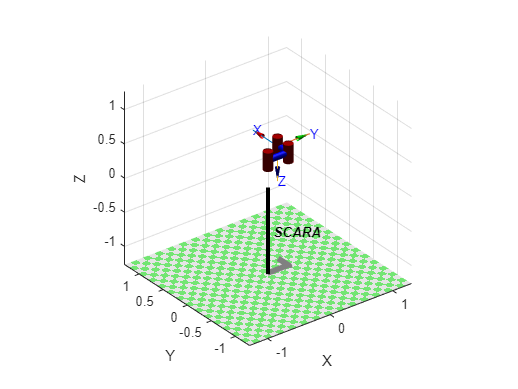

L(1) = Link('revolute','d',0.4,'a',0,'alpha',0,'modified');
L(2) = Link('revolute','d',0,'a',0.325,'alpha',0,'modified');
L(3) = Link('revolute','d',0,'a',0.225,'alpha',0,'modified');
L(4) = Link('prismatic','a',0,'alpha',pi,'modified');
% tool = transl(0, 0, -0.01);
L(4).qlim = [ 0.17  0.32];
% SCARA = SerialLink([L(1),L(2),L(3),L(4)], 'tool', tool);
SCARA = SerialLink([L(1),L(2),L(3),L(4)]);
SCARA.name = 'SCARA';
figure
SCARA.plot([0 pi/2 0 0.01])


% Maximum velocity for each joint

vmax = [(420/180)*pi; (720/180)*pi; (3000/180)*pi; 1.1  ];


## Trajectory 1


[t, theta] = taskSpaceTrajectory(T_04 , T_04, T_0A, T_0A, vmax)

t =          0         0         0         0         0         0         0         0         0         0         0    0.0001    0.0003    0.0004    0.0006    0.0007    0.0008    0.0010    0.0011    0.0013    0.0014    0.0015    0.0017    0.0018    0.0019    0.0021    0.0022    0.0024    0.0025    0.0026    0.0028    0.0029    0.0031    0.0032    0.0033    0.0035    0.0036    0.0038    0.0039    0.0040    0.0042    0.0043    0.0045    0.0046    0.0047    0.0049    0.0050    0.0051    0.0053    0.0054


theta =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708 

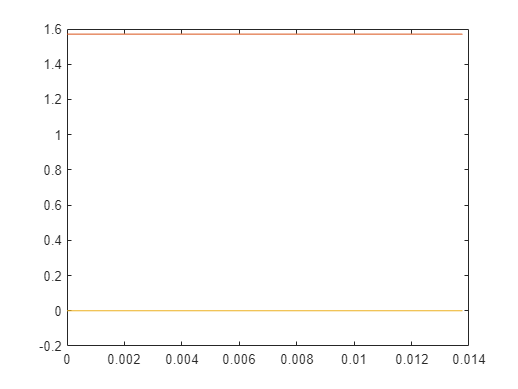


figure
plot(t, theta(1:3, :))

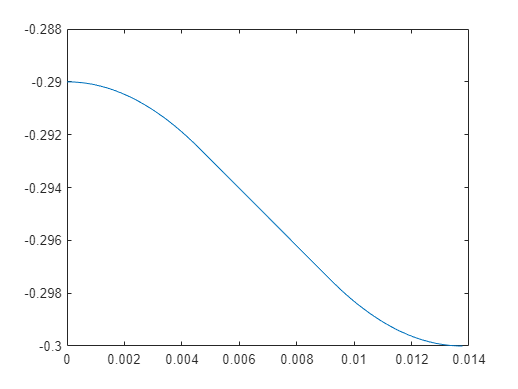

figure
plot(t, theta(4, :))

## Trajectory 2


[t, theta] = taskSpaceTrajectory(T_0A , T_0A1, T_0B1, T_0B, vmax)

t =          0    0.0017    0.0034    0.0051    0.0067    0.0084    0.0101    0.0118    0.0135    0.0152    0.0152    0.0182    0.0212    0.0243    0.0273    0.0304    0.0334    0.0364    0.0395    0.0425    0.0456    0.0486    0.0516    0.0547    0.0577    0.0608    0.0638    0.0668    0.0699    0.0729    0.0760    0.0790    0.0820    0.0851    0.0881    0.0912    0.0942    0.0972    0.1003    0.1033    0.1064    0.1094    0.1124    0.1155    0.1185    0.1216    0.1246    0.1276    0.1307    0.1337


theta =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0003   -0.0005   -0.0008   -0.0011   -0.0015   -0.0019   -0.0023   -0.0028   -0.0033   -0.0038   -0.0043   -0.0048   -0.0052   -0.0056   -0.0060   -0.0063   -0.0065   -0.0066   -0.0066   -0.0064   -0.0061   -0.0056   -0.0048   -0.0039   -0.0026   -0.0011    0.0007    0.0029    0.0055    0.0086    0.0121    0.0160    0.0204    0.0252    0.0304    0.0360    0.0421
    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5712    1.5722    1.5741    1.5766    1.5799    1.5838    1.5885    1.5939    1.6000    1.6068    1.6142    1.6223    1.6311    1.6406    1.6507    1.6614    1.6728    1.6847    1.6973    1.7104    1.7241    1.7384    1.7532    1.7685    1.7844    1.8007    1.8176    1.8349    1.8527    1.8709    1.8896    1.9086    1.9281    1.9476    1.9669    1.9861    2.0050    2.0237 

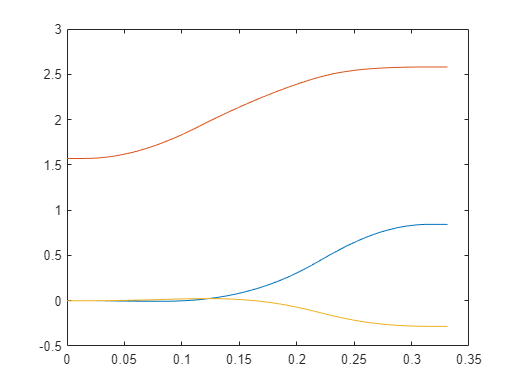


figure
plot(t, theta(1:3, :))

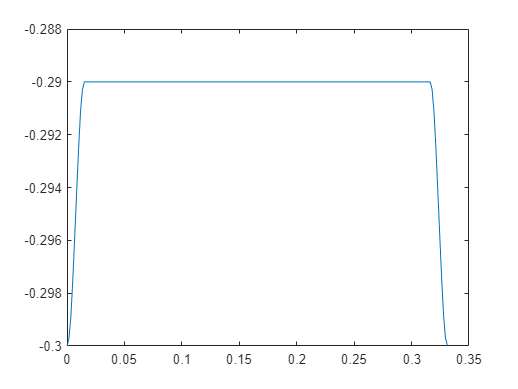

figure
plot(t, theta(4, :))

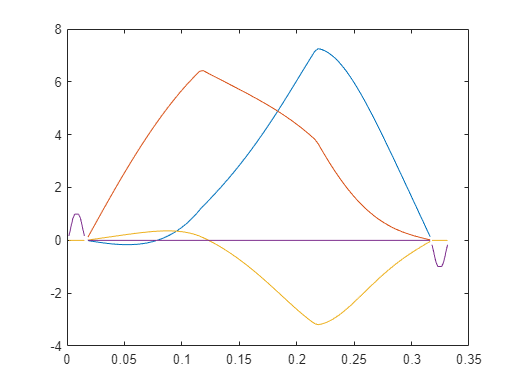


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

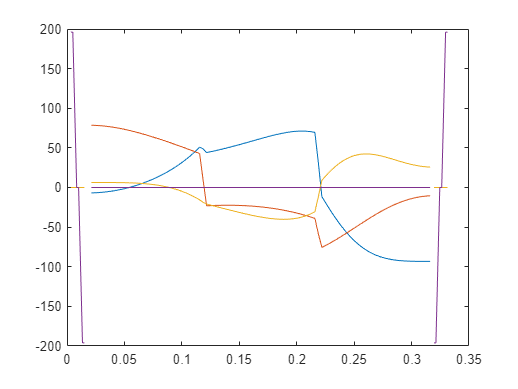


figure
plot(t(3:end), theta_dd)

## Trajectory 3


[t, theta] = taskSpaceTrajectory(T_0B , T_0B1, T_0A1, T_0A, vmax)

t =          0    0.0017    0.0034    0.0051    0.0067    0.0084    0.0101    0.0118    0.0135    0.0152    0.0152    0.0182    0.0212    0.0243    0.0273    0.0304    0.0334    0.0364    0.0395    0.0425    0.0456    0.0486    0.0516    0.0547    0.0577    0.0608    0.0638    0.0668    0.0699    0.0729    0.0760    0.0790    0.0820    0.0851    0.0881    0.0912    0.0942    0.0972    0.1003    0.1033    0.1064    0.1094    0.1124    0.1155    0.1185    0.1216    0.1246    0.1276    0.1307    0.1337


theta =     0.8436    0.8436    0.8436    0.8436    0.8436    0.8436    0.8436    0.8436    0.8436    0.8436    0.8436    0.8431    0.8418    0.8397    0.8367    0.8328    0.8280    0.8224    0.8160    0.8087    0.8005    0.7915    0.7816    0.7709    0.7593    0.7470    0.7338    0.7198    0.7050    0.6895    0.6733    0.6563    0.6387    0.6204    0.6015    0.5820    0.5620    0.5415    0.5206    0.4994    0.4779    0.4561    0.4341    0.4121    0.3903    0.3691    0.3487    0.3288    0.3097    0.2911
    2.5808    2.5808    2.5808    2.5808    2.5808    2.5808    2.5808    2.5808    2.5808    2.5808    2.5808    2.5808    2.5806    2.5804    2.5800    2.5796    2.5790    2.5783    2.5775    2.5765    2.5753    2.5740    2.5725    2.5707    2.5687    2.5665    2.5640    2.5612    2.5581    2.5546    2.5507    2.5465    2.5418    2.5366    2.5310    2.5249    2.5182    2.5110    2.5032    2.4948    2.4857    2.4760    2.4657    2.4546    2.4430    2.4310    2.4186    2.4060    2.3930 

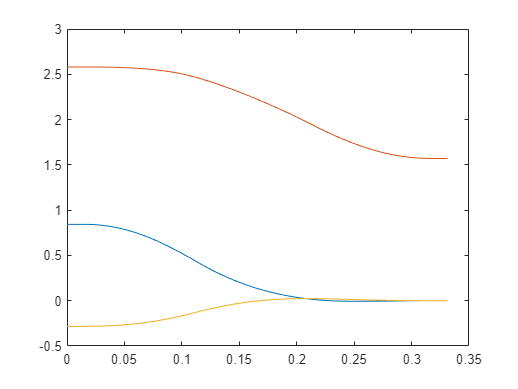


figure
plot(t, theta(1:3, :))

figure
plot(t, theta(4, :))

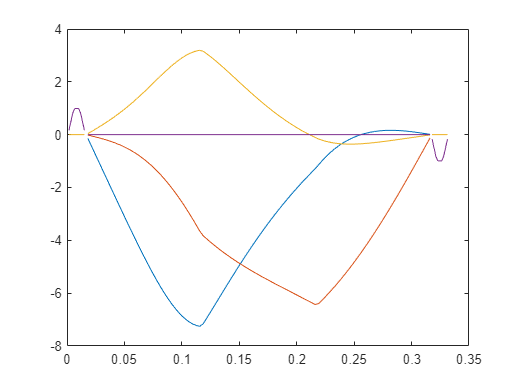


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

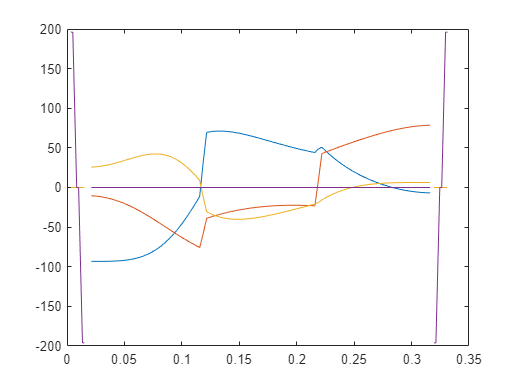


figure
plot(t(3:end), theta_dd)

## Trajectory 4


[t, theta] = taskSpaceTrajectory(T_0A , T_0A1, T_0C1, T_0C, vmax)

t =          0    0.0017    0.0034    0.0051    0.0067    0.0084    0.0101    0.0118    0.0135    0.0152    0.0152    0.0198    0.0244    0.0290    0.0337    0.0383    0.0429    0.0476    0.0522    0.0568    0.0615    0.0661    0.0707    0.0754    0.0800    0.0846    0.0893    0.0939    0.0985    0.1032    0.1078    0.1124    0.1170    0.1217    0.1263    0.1309    0.1356    0.1402    0.1448    0.1495    0.1541    0.1587    0.1634    0.1680    0.1726    0.1773    0.1819    0.1865    0.1912    0.1958


theta =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0001   -0.0003   -0.0005   -0.0008   -0.0011   -0.0014   -0.0018   -0.0022   -0.0026   -0.0029   -0.0033   -0.0036   -0.0038   -0.0040   -0.0041   -0.0040   -0.0038   -0.0033   -0.0027   -0.0018   -0.0007    0.0008    0.0026    0.0048    0.0075    0.0106    0.0143    0.0186    0.0235    0.0292    0.0356    0.0429    0.0510    0.0599    0.0694    0.0797    0.0908    0.1027
    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5713    1.5726    1.5749    1.5781    1.5821    1.5871    1.5930    1.5997    1.6073    1.6157    1.6250    1.6351    1.6460    1.6577    1.6702    1.6835    1.6974    1.7122    1.7276    1.7437    1.7605    1.7779    1.7959    1.8146    1.8338    1.8536    1.8739    1.8947    1.9160    1.9378    1.9600    1.9826    2.0056    2.0286    2.0513    2.0736    2.0955    2.1171 

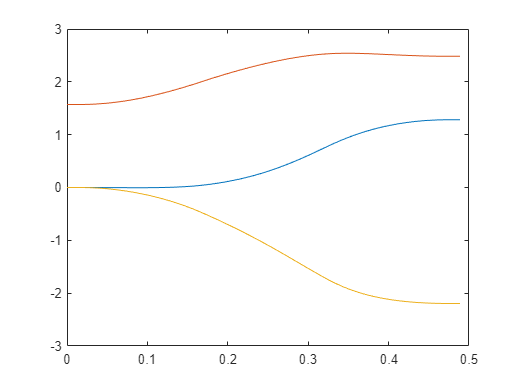


figure
plot(t, theta(1:3, :))

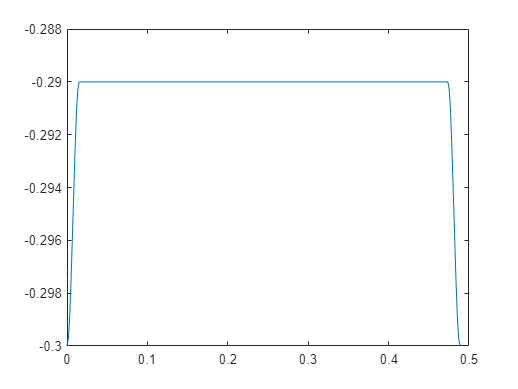

figure
plot(t, theta(4, :))

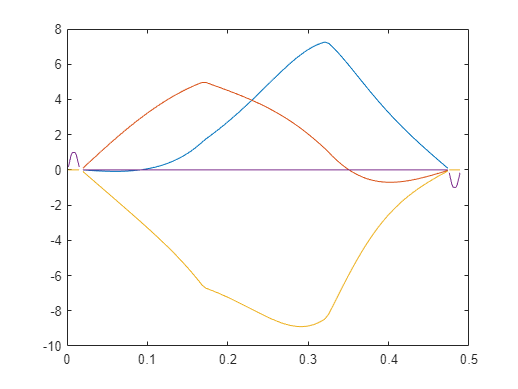


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

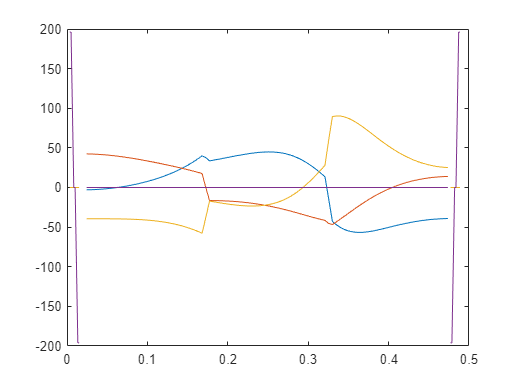


figure
plot(t(3:end), theta_dd)

## Trajectory 5


[t, theta] = taskSpaceTrajectory(T_0C , T_0C1, T_0A1, T_0A, vmax)

t =          0    0.0017    0.0034    0.0051    0.0067    0.0084    0.0101    0.0118    0.0135    0.0152    0.0152    0.0198    0.0244    0.0290    0.0337    0.0383    0.0429    0.0476    0.0522    0.0568    0.0615    0.0661    0.0707    0.0754    0.0800    0.0846    0.0893    0.0939    0.0985    0.1032    0.1078    0.1124    0.1170    0.1217    0.1263    0.1309    0.1356    0.1402    0.1448    0.1495    0.1541    0.1587    0.1634    0.1680    0.1726    0.1773    0.1819    0.1865    0.1912    0.1958


theta =     1.2821    1.2821    1.2821    1.2821    1.2821    1.2821    1.2821    1.2821    1.2821    1.2821    1.2821    1.2816    1.2804    1.2783    1.2753    1.2715    1.2669    1.2613    1.2549    1.2476    1.2394    1.2302    1.2201    1.2091    1.1970    1.1840    1.1699    1.1548    1.1385    1.1212    1.1028    1.0831    1.0624    1.0404    1.0172    0.9928    0.9672    0.9404    0.9123    0.8832    0.8529    0.8215    0.7891    0.7558    0.7222    0.6889    0.6559    0.6234    0.5915    0.5601
    2.4840    2.4840    2.4840    2.4840    2.4840    2.4840    2.4840    2.4840    2.4840    2.4840    2.4840    2.4841    2.4846    2.4853    2.4864    2.4877    2.4893    2.4911    2.4932    2.4956    2.4981    2.5008    2.5037    2.5068    2.5099    2.5131    2.5164    2.5196    2.5229    2.5260    2.5290    2.5317    2.5343    2.5365    2.5384    2.5398    2.5407    2.5410    2.5407    2.5397    2.5379    2.5352    2.5316    2.5270    2.5214    2.5149    2.5075    2.4993    2.4903 

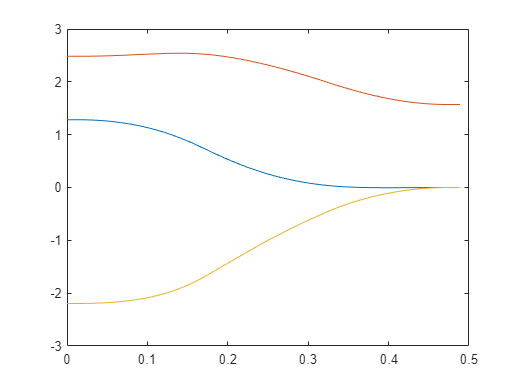


figure
plot(t, theta(1:3, :))

figure
plot(t, theta(4, :))

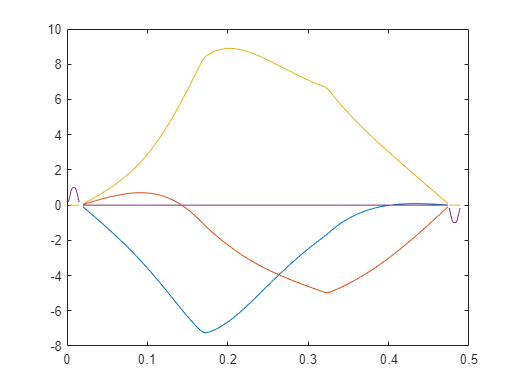


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

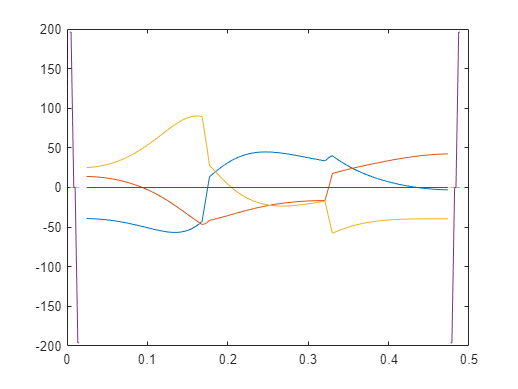


figure
plot(t(3:end), theta_dd)

## Trajectory 6

[t, theta] = taskSpaceTrajectory(T_0A , T_0A1, T_0D1, T_0D, vmax)

t =          0    0.0017    0.0034    0.0051    0.0067    0.0084    0.0101    0.0118    0.0135    0.0152    0.0152    0.0185    0.0219    0.0253    0.0287    0.0320    0.0354    0.0388    0.0422    0.0455    0.0489    0.0523    0.0557    0.0591    0.0624    0.0658    0.0692    0.0726    0.0759    0.0793    0.0827    0.0861    0.0895    0.0928    0.0962    0.0996    0.1030    0.1063    0.1097    0.1131    0.1165    0.1198    0.1232    0.1266    0.1300    0.1334    0.1367    0.1401    0.1435    0.1469


theta =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0003    0.0005    0.0008    0.0012    0.0017    0.0023    0.0030    0.0038    0.0048    0.0059    0.0071    0.0086    0.0103    0.0122    0.0144    0.0168    0.0196    0.0227    0.0261    0.0300    0.0343    0.0390    0.0443    0.0501    0.0565    0.0635    0.0712    0.0796    0.0888    0.0988    0.1097    0.1214    0.1336    0.1464    0.1599    0.1739    0.1885
    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5712    1.5724    1.5743    1.5770    1.5805    1.5848    1.5898    1.5956    1.6021    1.6093    1.6173    1.6259    1.6352    1.6452    1.6558    1.6671    1.6789    1.6914    1.7044    1.7179    1.7320    1.7465    1.7616    1.7770    1.7929    1.8091    1.8257    1.8426    1.8598    1.8772    1.8948    1.9126    1.9305    1.9483    1.9655    1.9824    1.9987    2.0145 

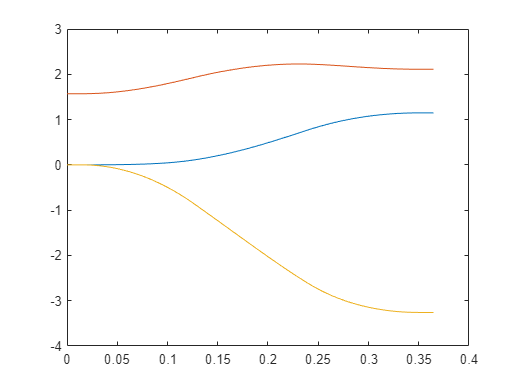


figure
plot(t, theta(1:3, :))

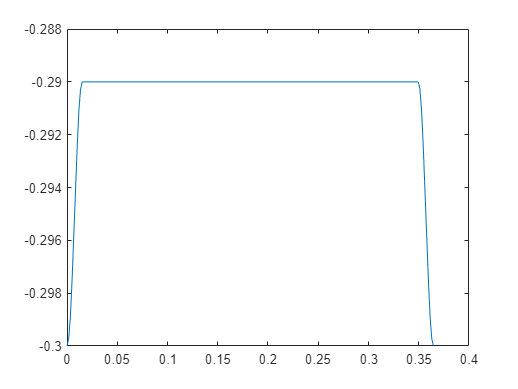

figure
plot(t, theta(4, :))

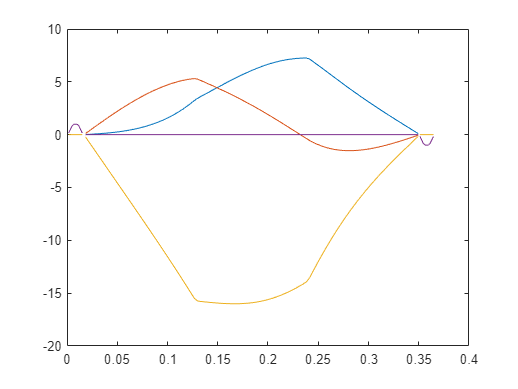


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

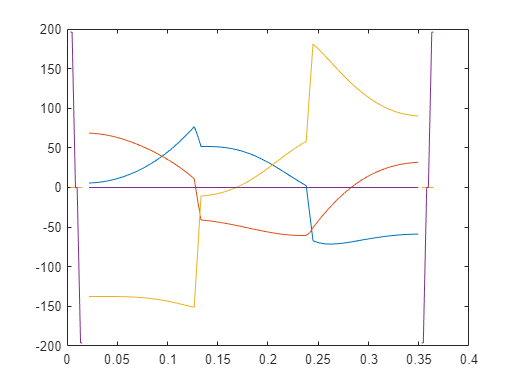


figure
plot(t(3:end), theta_dd)

## Trajectory 7

[t, theta] = taskSpaceTrajectory(T_0D , T_0D1, T_0A1, T_0A, vmax)

t =          0    0.0017    0.0034    0.0051    0.0067    0.0084    0.0101    0.0118    0.0135    0.0152    0.0152    0.0185    0.0219    0.0253    0.0287    0.0320    0.0354    0.0388    0.0422    0.0455    0.0489    0.0523    0.0557    0.0591    0.0624    0.0658    0.0692    0.0726    0.0759    0.0793    0.0827    0.0861    0.0895    0.0928    0.0962    0.0996    0.1030    0.1063    0.1097    0.1131    0.1165    0.1198    0.1232    0.1266    0.1300    0.1334    0.1367    0.1401    0.1435    0.1469


theta =     1.1477    1.1477    1.1477    1.1477    1.1477    1.1477    1.1477    1.1477    1.1477    1.1477    1.1477    1.1473    1.1463    1.1446    1.1423    1.1393    1.1356    1.1312    1.1261    1.1203    1.1139    1.1067    1.0989    1.0903    1.0810    1.0710    1.0603    1.0488    1.0365    1.0235    1.0098    0.9952    0.9799    0.9638    0.9469    0.9291    0.9106    0.8912    0.8711    0.8501    0.8283    0.8057    0.7824    0.7582    0.7337    0.7092    0.6848    0.6605    0.6362    0.6121
    2.1113    2.1113    2.1113    2.1113    2.1113    2.1113    2.1113    2.1113    2.1113    2.1113    2.1113    2.1114    2.1120    2.1129    2.1141    2.1157    2.1177    2.1200    2.1226    2.1255    2.1287    2.1322    2.1360    2.1400    2.1443    2.1488    2.1534    2.1582    2.1631    2.1681    2.1732    2.1783    2.1834    2.1885    2.1935    2.1983    2.2030    2.2074    2.2115    2.2153    2.2187    2.2217    2.2241    2.2260    2.2272    2.2277    2.2275    2.2267    2.2251 

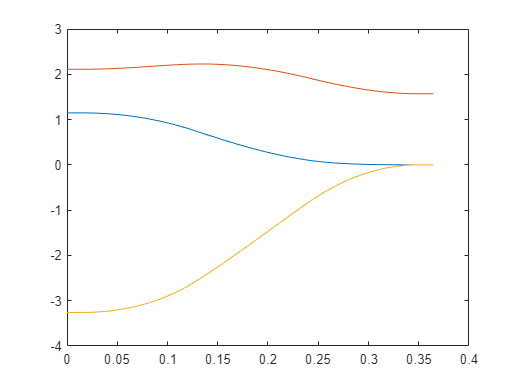


figure
plot(t, theta(1:3, :))

figure
plot(t, theta(4, :))

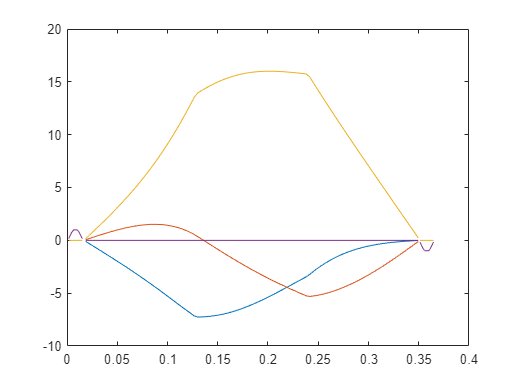


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

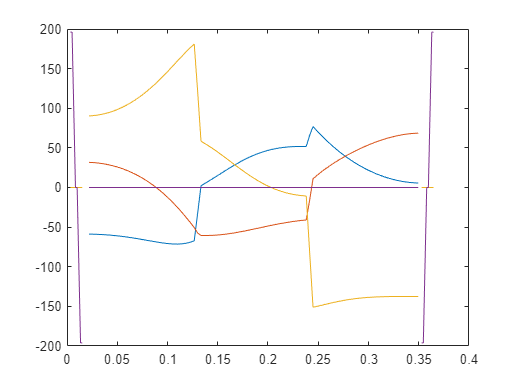


figure
plot(t(3:end), theta_dd)

## Trajectory 8

[t, theta] = taskSpaceTrajectory(T_0A , T_0A1, T_0E1, T_0E, vmax)

t =          0    0.0017    0.0034    0.0051    0.0067    0.0084    0.0101    0.0118    0.0135    0.0152    0.0152    0.0176    0.0200    0.0224    0.0248    0.0272    0.0296    0.0321    0.0345    0.0369    0.0393    0.0417    0.0441    0.0465    0.0490    0.0514    0.0538    0.0562    0.0586    0.0610    0.0634    0.0659    0.0683    0.0707    0.0731    0.0755    0.0779    0.0803    0.0828    0.0852    0.0876    0.0900    0.0924    0.0948    0.0972    0.0997    0.1021    0.1045    0.1069    0.1093


theta =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0003    0.0005    0.0008    0.0012    0.0016    0.0022    0.0028    0.0036    0.0044    0.0054    0.0065    0.0077    0.0091    0.0106    0.0124    0.0143    0.0164    0.0188    0.0214    0.0243    0.0275    0.0310    0.0348    0.0389    0.0435    0.0484    0.0538    0.0596    0.0660    0.0728    0.0802    0.0880    0.0962    0.1048    0.1136    0.1229    0.1325
    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5708    1.5711    1.5720    1.5735    1.5756    1.5783    1.5815    1.5854    1.5898    1.5948    1.6004    1.6065    1.6132    1.6204    1.6281    1.6363    1.6451    1.6543    1.6640    1.6742    1.6848    1.6958    1.7072    1.7191    1.7313    1.7439    1.7568    1.7701    1.7836    1.7974    1.8115    1.8258    1.8404    1.8551    1.8698    1.8841    1.8982    1.9120    1.9255 

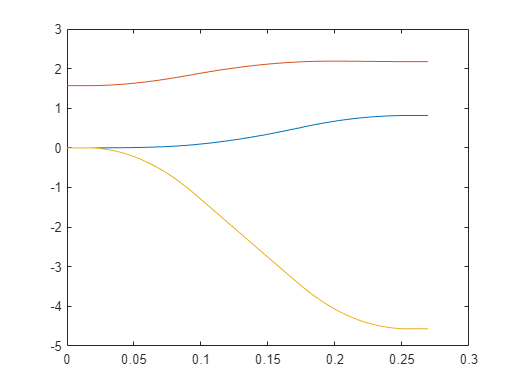


figure
plot(t, theta(1:3, :))

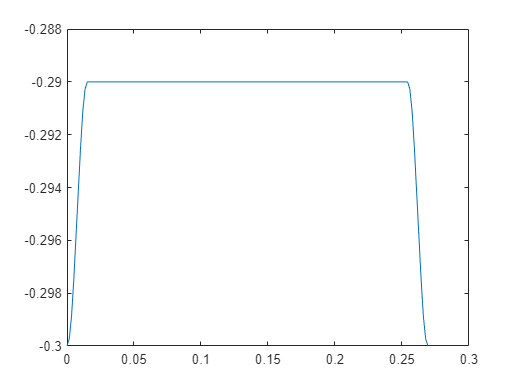

figure
plot(t, theta(4, :))

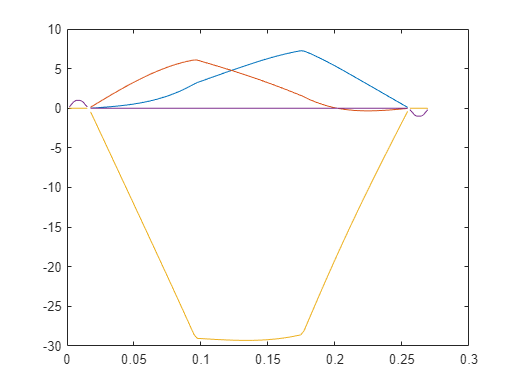


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

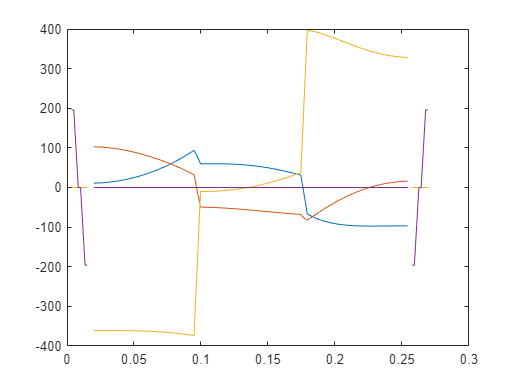


figure
plot(t(3:end), theta_dd)

## Trajectory 9

[t, theta] = taskSpaceTrajectory(T_0E , T_0E1, T_0A1, T_0A, vmax)

t =          0    0.0017    0.0034    0.0051    0.0067    0.0084    0.0101    0.0118    0.0135    0.0152    0.0152    0.0176    0.0200    0.0224    0.0248    0.0272    0.0296    0.0321    0.0345    0.0369    0.0393    0.0417    0.0441    0.0465    0.0490    0.0514    0.0538    0.0562    0.0586    0.0610    0.0634    0.0659    0.0683    0.0707    0.0731    0.0755    0.0779    0.0803    0.0828    0.0852    0.0876    0.0900    0.0924    0.0948    0.0972    0.0997    0.1021    0.1045    0.1069    0.1093


theta =     0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8165    0.8162    0.8154    0.8140    0.8120    0.8095    0.8064    0.8027    0.7985    0.7937    0.7883    0.7824    0.7758    0.7688    0.7611    0.7529    0.7442    0.7348    0.7249    0.7144    0.7034    0.6919    0.6797    0.6671    0.6539    0.6401    0.6259    0.6111    0.5959    0.5802    0.5640    0.5474    0.5304    0.5129    0.4954    0.4781    0.4609    0.4440    0.4273    0.4108
    2.1772    2.1772    2.1772    2.1772    2.1772    2.1772    2.1772    2.1772    2.1772    2.1772    2.1772    2.1772    2.1774    2.1776    2.1779    2.1783    2.1788    2.1794    2.1800    2.1807    2.1814    2.1821    2.1829    2.1837    2.1845    2.1853    2.1860    2.1867    2.1873    2.1878    2.1883    2.1885    2.1887    2.1886    2.1883    2.1878    2.1870    2.1860    2.1846    2.1829    2.1807    2.1782    2.1752    2.1718    2.1679    2.1636    2.1589    2.1538    2.1483 

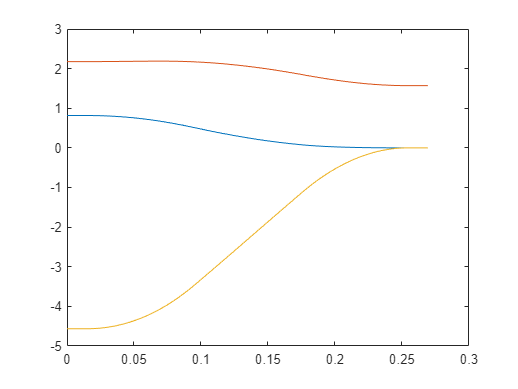


figure
plot(t, theta(1:3, :))

figure
plot(t, theta(4, :))

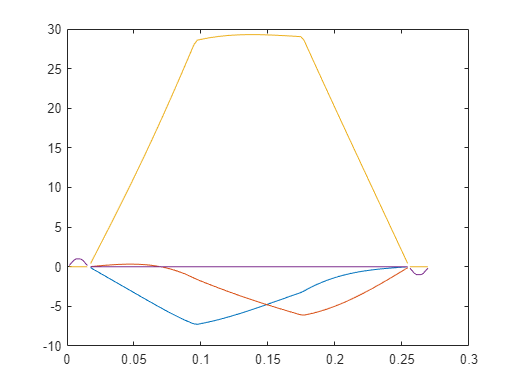


theta_d = [];
theta_dd = [];

for i=1:4
    theta_d(i, :) = diff(theta(i,1:end))./diff(t);
end

for i=1:4
    theta_dd(i, :) = diff(theta_d(i,1:end))./diff(t(2:end));
end

figure
plot(t(2:end),theta_d)

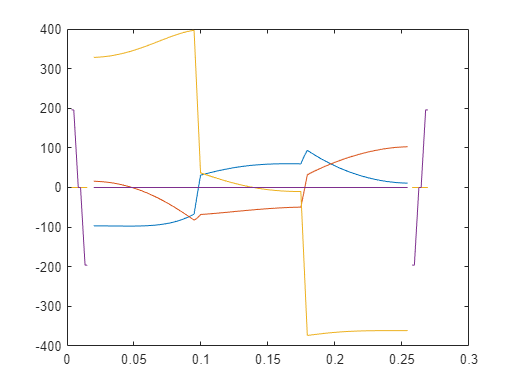


figure
plot(t(3:end), theta_dd)